%% WV Eddy
%alongtrackLonLat from OceanDB
%eddyPath_track from ssh max closed contour centroid
%eddy_field is an array of eddy field in (x,y,t,ssh)
clear all

## 1. Extract tracks along the eddy path

% define domain
readdir = 'G:\My Drive\AlongTrack\';
filename = 'BetaEddyOne.nc';
% Load Model
x_QG = ncread([readdir, filename], 'x'); %meters
y_QG = ncread([readdir, filename], 'y'); %meters
ssh = squeeze(ncread([readdir, filename], 'ssh')); %meter;% matrix order in x,y,z

totalDays = size(ssh, 3);
x = x_QG - mean(x_QG);
y = y_QG - mean(y_QG);

eddy_field.x = x;
eddy_field.y = y;
eddy_field.t = [1:totalDays];
eddy_field.ssh = ssh;

%find eddy center
[center_xoyo,amplitude,radius,core_xy] = findEddyCentroid(x, y, ssh,'thresholdratio',0.9,'GetBoundary', true);
eddyPath.xe = center_xoyo(:,1);
eddyPath.ye = center_xoyo(:,2);

%if you want to change the eddyPath to a function handle
eddyPath_fun_t.xe = @(t) interp1(eddy_field.t, eddyPath.xe, t, 'linear', 'extrap');
eddyPath_fun_t.ye = @(t) interp1(eddy_field.t, eddyPath.ye, t, 'linear', 'extrap');

% extract track - takes somes time bc it loads the entire track matrix
my_readdir = 'G:\My Drive\AlongTrack\';
alongtrackLatLon = alongtrackFromXYDomain(x,y,totalDays,lono=-40,readdir=my_readdir); %options: lato=24, lono=305
alongtrackXY = latlon2xy_centered(alongtrackLatLon);


## 2. Apply OSSE on your choice of an analytical eddy shape

%Output: alongtrack - contains arrays of lon,lat,x,y,t,ssh of OSSE 
% apply OSSE on an eddy_field from QG model in (x,y,t)
alongtrack = subsampleOSSE(alongtrackXY,eddy_field);


## 3. Plots and Videos of OSSE

%% plot eddy path with alongtrack, and OSSE
alongtrackLatLon.ssh=alongtrack.ssh; %plotAlongtrack takes in lat lon info
plotAlongtrack(alongtrackLatLon,eddyPath);

%% make video of the propagating eddy
video_name = 'eddy_field_QGmodel';
makePropagatingVideo(x,y,totalDays,eddy_model,video_name)


## 4. Eddy composites

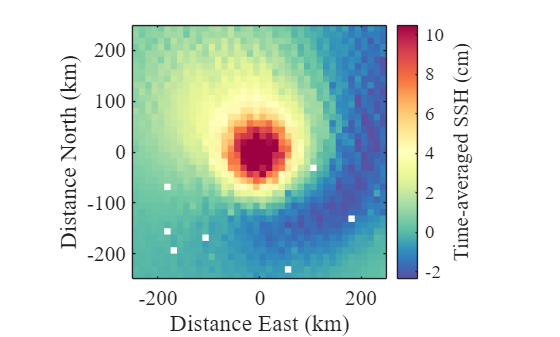

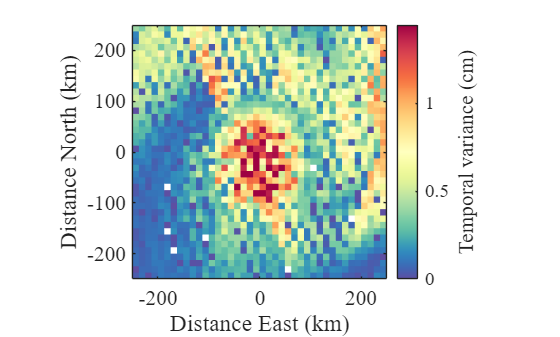

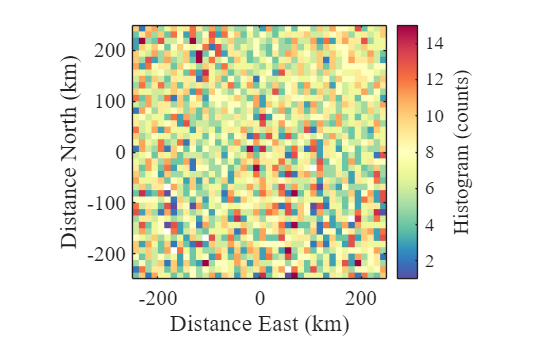

%eddy center from eddyPath_track, which is from ssh max closed contour centroid
% time-averaged eddy composite
[mz_xy, xmid_xy, ymid_xy, numz_xy, stdz_xy] = composite2D(alongtrack,eddyPath_fun_t);% options: bin_size=12.5*1e3

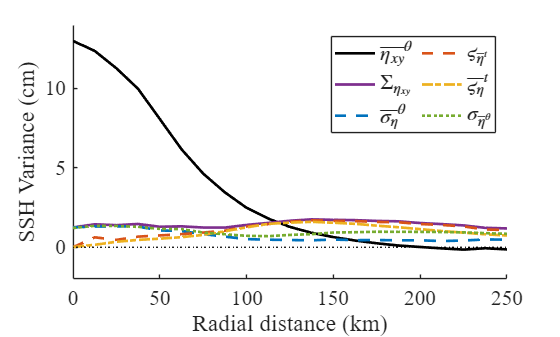

% time-averaged radial profile
[mz_r, rmid_r, numz_r, stdz_r] = radialProfile(alongtrack,eddyPath_fun_t);

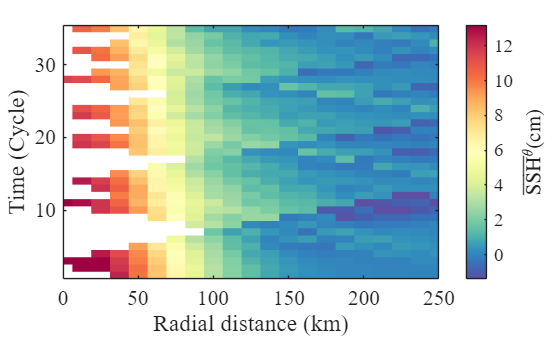

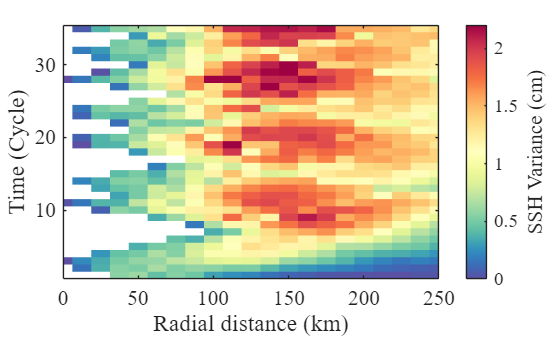

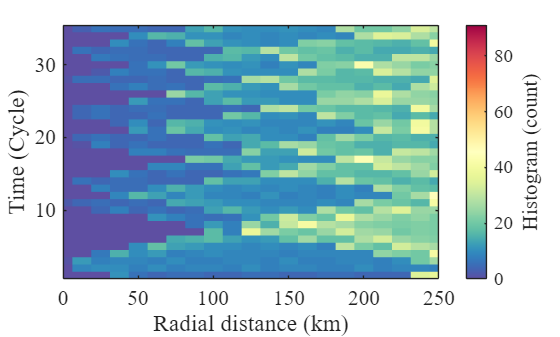

% radialProfile over time
[mz_rt, rmid_rt, tmid_rt, numz_rt, stdz_rt] = radialProfileTime(alongtrack,eddyPath_fun_t);

## 6. Gaussian fit

eddyFit_fun = @(x,y,t,A,L,x0,y0,cx,cy) A.*exp(-((x-x0-cx*t).^2 + (y-y0-cy*t).^2)/L^2);
initialParams = [];
params = FitAlongTrackLatLonEddyModel(alongtrackLatLon, eddyFit_fun, initialParams);
% paramsCell = FitAlongTrackLatLonToEddyModelWindowed(alongtrackLatLon, eddyFit_fun, initialParams, windowLength);